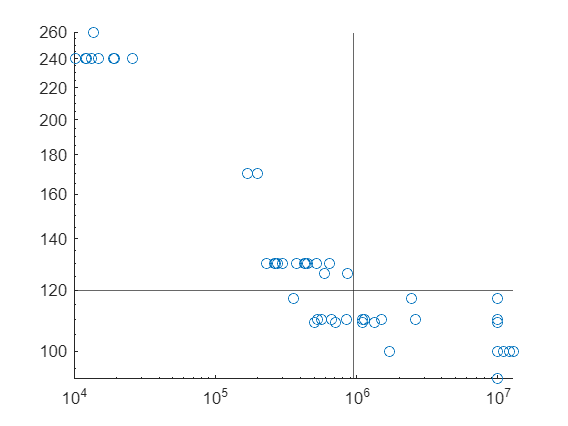

clear all
clf
format shortg

% data = xlsread("fatigue_data.xlsx")r;
load("fatigue_data.mat")
% data_size = size(data)

% specimen = data(:,0)
% sigma_m = data(:,1);
% sigma_a = data(:,2);
% N = data(:,3);
% RO = data(:,4)


scatter(N,S)
yscale log
xscale log

N_D = 9.5*1e5;
S_D = 120;
yline(S_D)
xline(N_D)

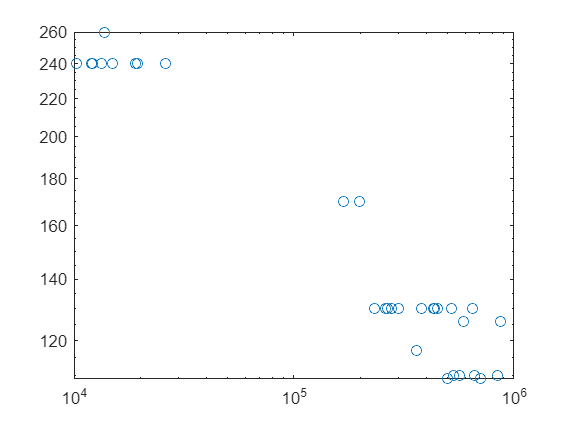



data = [N, S, RO];

% data3 = data((data(:,1)<N_D) && (data(:,3)==0))

data2 = [];

for i = 1:length(N)
    if N(i) < N_D && RO(i)==0
        data2(end+1,1:2) = data(i,1:2);
    end
end


N2 = data2(:,1);

S2 = data2(:,2);

loglog(N2, S2,"o")

% yscale log
% xscale log
a=fitlm(N2, S2)

a = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________

    (Intercept)        218.95        8.5769     25.528    2.0083e-21
    x1             -0.0001754    2.0248e-05    -8.6627    1.5414e-09


Number of observations: 31, Error degrees of freedom: 29
Root Mean Squared Error: 29.5
R-squared: 0.721,  Adjusted R-Squared: 0.712
F-statistic vs. constant model: 75, p-value = 1.54e-09

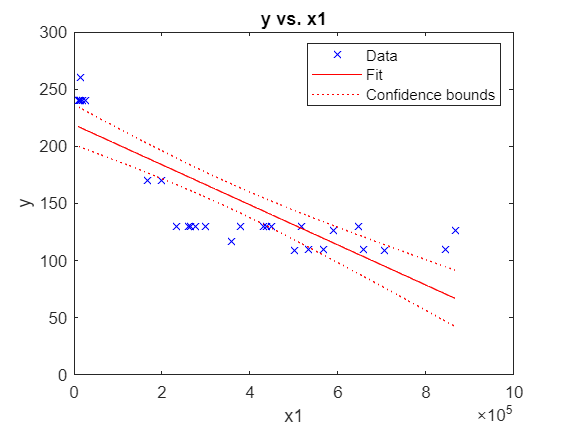

plot(a)

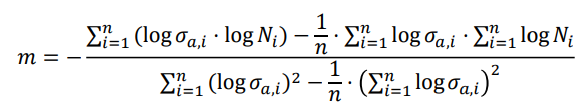


N2_log = log10(N2)

N2_log =        5.7143
       5.4232
       5.6513
       5.8109
       5.6345
       5.3655
       5.4425
       5.4742
       5.5775
       5.4166


S2_log = log10(S2)

S2_log =        2.1139
       2.1139
       2.1139
       2.1139
       2.1139
       2.1139
       2.1139
       2.1139
       2.1139
       2.1139



a=fitlm(N2_log, S2_log)

a = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE         tStat       pValue  
                   ________    _________    _______    __________

    (Intercept)      3.1918     0.046612     68.477    1.2687e-33
    x1             -0.19383    0.0088824    -21.822    1.5256e-19


Number of observations: 31, Error degrees of freedom: 29
Root Mean Squared Error: 0.0336
R-squared: 0.943,  Adjusted R-Squared: 0.941
F-statistic vs. constant model: 476, p-value = 1.53e-19

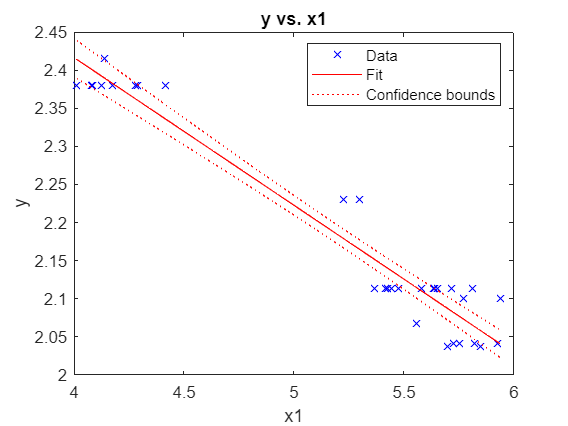

plot(a)


m = ( sum(log(S2) .* log(N2)) - 1/length(N2)) 

m =        1852.4
